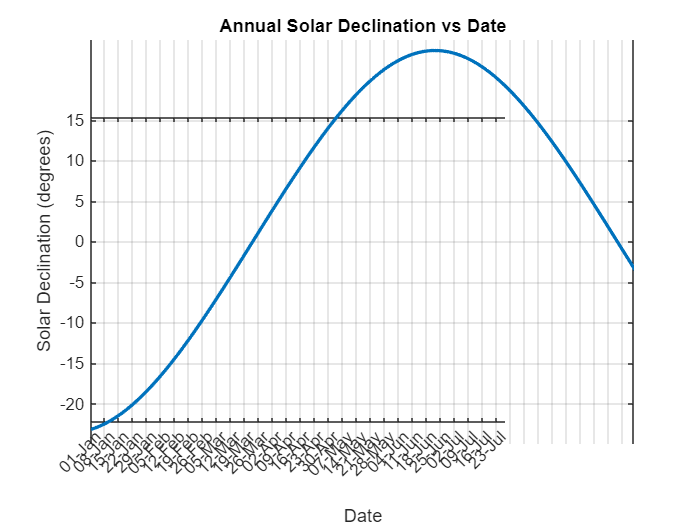

% Define the year
year_val = 2026;

% Create datetime array for all days in the year
dates = datetime(year_val,1,1):datetime(year_val,12,31);

% Convert datetime to day-of-year
n = day(dates,'dayofyear');

delta_rad = asin(0.4 * sin((360/365)*(n - 82) * pi/180));
delta_deg = delta_rad * 180/pi;

figure;
plot(dates, delta_deg, 'LineWidth', 2);
grid on;

xlabel('Date');
ylabel('Solar Declination (degrees)');
title('Annual Solar Declination vs Date');

% Format x-axis to show every day
ax = gca;
ax.XTick = dates(1:7:end); % Tick every 7 days to avoid clutter
ax.XTickLabel = datestr(dates(1:7:end),'dd-mmm'); % Show day-month format
xtickangle(45); % Rotate labels for readability